load('playpensample.mat');
theta = theta(r>0);
r = r(r>0);
theta = theta(r<5);
r = r(r<5);
[x,y] = pol2cart(deg2rad(theta),r);
xOrig = x;
yOrig = y;



starts = [];
vects = [];

while(length(x)>1)
    %plot(x,y,'bs')
    figure
    [bestStart,bestVect,ptsOnLine] = findLine(x, y, .05, 100);
    starts = [starts bestStart];
    vects = [vects bestVect];
    x = x(~ptsOnLine);
    y = y(~ptsOnLine);  
end

bestStart =     0.5390
   -0.0662


bestVect =    -0.4424
    0.5629


bestStart =     0.6031
   -0.1392


bestVect =    -0.2221
    0.3191


bestStart =     0.0722
   -1.3781


bestVect =     0.5910
    0.3949


bestStart =    -0.2249
   -1.6003


bestVect =     1.2642
    0.8877


bestStart =     0.2530
    0.3124


bestVect =    -0.0237
    0.0275


bestStart =     0.2680
    0.2874


bestVect =    -0.2215
    0.2658


bestStart =    -0.2047
    0.8867


bestVect =     0.0110
   -0.8004


bestStart =    -0.1869
    0.1935


bestVect =    -0.0372
   -0.1417


bestStart =    -0.3028
    0.7889


bestVect =    -1.1450
   -0.8141


bestStart =    -0.1616
    0.8314


bestVect =    -0.3103
   -0.2094


bestStart =    -0.8353
   -0.2395


bestVect =     0.6600
   -0.7551


bestStart =    -0.9306
   -0.1641


bestVect =     0.2379
   -0.1977


bestStart =    -2.2255
   -2.0753


bestVect =    -0.1624
    0.2759


bestStart =    -2.4230
   -1.7604


bestVect =     0.6092
   -0.9363


bestStart =    -0.7482
   -0.4320


bestVect =     0.4572
   -0.4133


bestStart =    -0.3910
   -0.8017


bestVect =     0.2157
   -0.2289


bestStart =    -0.0905
    0.7375


bestVect =    -1.5442
   -0.8805


bestStart =    -1.2771
    0.1117


bestVect =    -0.5367
   -0.3608


bestStart =    -0.0754
    0.7171


bestVect =     0.0142
   -0.0177


bestStart =    -0.0482
    0.6893


bestVect =    -0.0917
    0.1168


bestStart =     0.3220
    0.2339


bestVect =    -1.1531
   -0.7737


bestStart =     0.3285
    0.2300


bestVect =    -0.0165
    0.0226


bestStart =    -0.4591
   -0.8635


bestVect =     1.2457
    0.5133


bestStart =    -0.5598
   -0.9317


bestVect =     0.1349
    0.0962


bestStart =    -0.8311
   -0.5397


bestVect =    -1.6845
   -1.2217


bestStart =    -0.7482
   -0.4320


bestVect =    -0.1109
   -0.1471


bestStart =    -2.5156
   -1.7615


bestVect =     3.3022
    1.4113


bestStart =     0.8130
   -0.3791


bestVect =    -0.0471
    0.0540


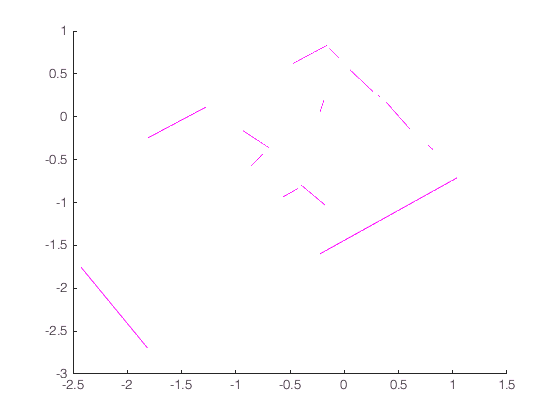

clf
%plot(xOrig,yOrig, 'ks');
hold on
t = linspace(0, 1);
for i = 1:size(vects,2)
    plot(t*vects(1,i)+starts(1,i),t*vects(2,i)+starts(2,i),'m');
end

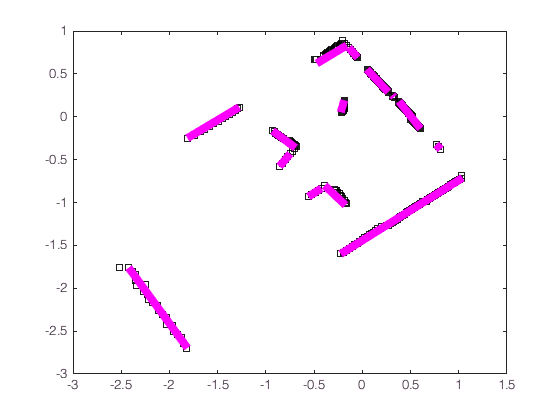

figure
clf
plot(xOrig,yOrig, 'ks');
hold on
t = linspace(0, 1);
for i = 1:size(vects,2)
    plot(t*vects(1,i)+starts(1,i),t*vects(2,i)+starts(2,i),'m','LineWidth', 6);
end

function res = dist2line(x, y, start, vect)
    M = [x y];
    M = M - start';
    normal = [-vect(2) ; vect(1)];
    normal = normal/norm(normal);
    res = abs(M * normal);
end
function res = distOnLine(x, y, start, vect)
    M = [x y];
    M = M - start';
    projVect = vect/norm(vect);
    res = M * projVect;
end
function [bestStart,bestVect,ptsOnLine] = findLine(x, y, epsilon, nTries)
    nPoints = length(x);

    bestStart = [0; 0];
    bestVect = [0; 0];
    bestScore = -Inf;
    ptsOnLine = [];
    
    for succ = 1:nTries
        i=0;
        j=0;
        while(i==j)
            i = randi(nPoints);
            j = randi(nPoints);
        end
        a = [x(i);y(i)];
        b = [x(j);y(j)];
        vect = b-a;
        dist = dist2line(x,y,a,vect);
        score = sum(dist < epsilon);
        if(score > bestScore)
            bestScore = score;
            bestStart = a;
            bestVect = vect;
            ptsOnLine = dist < epsilon;
        end
    end
    ptsOnLine = removeGaps(x, y, ptsOnLine, bestStart, bestVect, 2);
    [bestStart, bestVect] = linRegPCA(x(ptsOnLine), y(ptsOnLine));
end
function pts = removeGaps(x, y, ptsOnLine, start, vect, epsilon)
    xsOnLine = x(ptsOnLine);
    ysOnLine = y(ptsOnLine); 
    ts = distOnLine(xsOnLine, ysOnLine, start, vect/norm(vect));
    [tsSorted,indicies] = sort(ts);
    diffs = diff(tsSorted);
    meanDiff = mean(diffs);
    breaks = [0; find(diffs>meanDiff*epsilon); length(ts)];
    lengths = diff(breaks);
    [~,maxSegment] = max(lengths);
    indiciesOnLine = breaks(maxSegment)+1:breaks(maxSegment+1);
    localIndicies = indicies(indiciesOnLine);
    
    L = [xsOnLine(localIndicies) ysOnLine(localIndicies)];
    G = [x y];
    
    pts = ismember(G, L, 'rows');
end
function [mu,v] = linRegPCA(x,y)
    XY = [x y];
    A = XY;
    mu = mean(A);
    A = A - mu;
    mu = mu';
    [~, ~, V] = svd(A,'econ');
    v = V(:,1);
    ts = distOnLine(x, y, mu, v);
    [tmin,minIndex] = min(ts);
    tmax = max(ts);
    mu = XY(minIndex,:)';
    len = tmax-tmin;
    v = v * len;
end